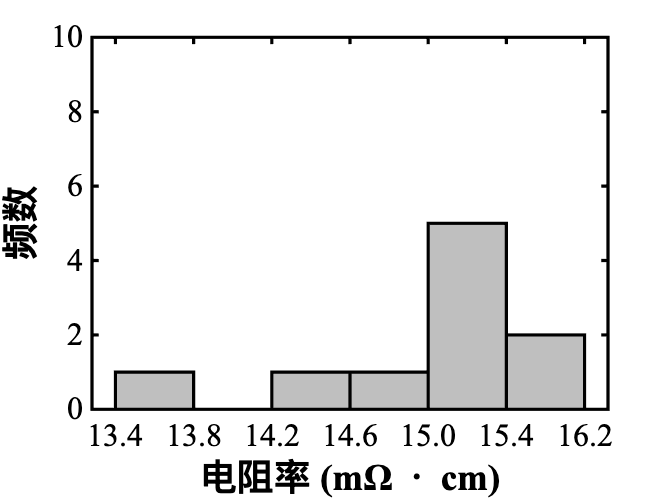

% =========================================================================
% 学术期刊发表级：薄片电阻率直方图
% =========================================================================

% 1. 定义真实数据
counts = [1, 0, 1, 1, 5, 2]; 
x_labels = {'13.4', '13.8', '14.2', '14.6', '15.0', '15.4', '16.2'};

% 2. 创建纯白背景画布 (符合出版标准)
figure('Color', 'w', 'Position', [200, 200, 600, 450]);
hold on;

% 3. 设置学术配色 (黑白灰，确保黑白打印绝对清晰)
barColor = [0.75, 0.75, 0.75]; % 标准学术灰
edgeColor = 'k';               % 纯黑边框

% 4. 绘制柱状图 (去掉柱子上的数字，学术图表通常依靠坐标轴读数)
for i = 1:length(counts)
    if counts(i) > 0
        x_left = i - 0.5;
        x_right = i + 0.5;
        fill([x_left, x_right, x_right, x_left], [0, 0, counts(i), counts(i)], ...
             barColor, 'EdgeColor', edgeColor, 'LineWidth', 1.2);
    end
end

% 5. 坐标轴核心设置 (学术规范的关键)
ylim([0, 10]);
yticks(0:2:10);
xlim([0.2, 6.8]);
xticks(0.5:1:6.5);
xticklabels(x_labels);

% 开启全包围边框 (Box on)，刻度朝内 (in)，加粗坐标轴 (1.2pt)
set(gca, 'Box', 'on', 'TickDir', 'in', 'LineWidth', 1.2, ...
         'XColor', 'k', 'YColor', 'k', 'XMinorTick', 'off', 'YMinorTick', 'off');

% 设置全局坐标轴字体为 Times New Roman (西文和数字的标准要求)
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);

% 6. 添加轴标签
% 注意：如果是投英文 SCI，请将中文全部替换为英文 (e.g., 'Frequency', 'Sheet Resistivity')
% 这里演示混合排版：中文使用宋体/默认字体，英文/符号使用 Times New Roman 或 Tex
xlabel('电阻率 (m\Omega \cdot cm)', 'Interpreter', 'tex', ...
       'FontSize', 14, 'FontWeight', 'bold', 'Color', 'k');

ylabel('频数', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'k');

% (注意：移除了内部的主标题，发表时请在 Word/LaTeX 的 \caption{} 中添加标题)

hold off;

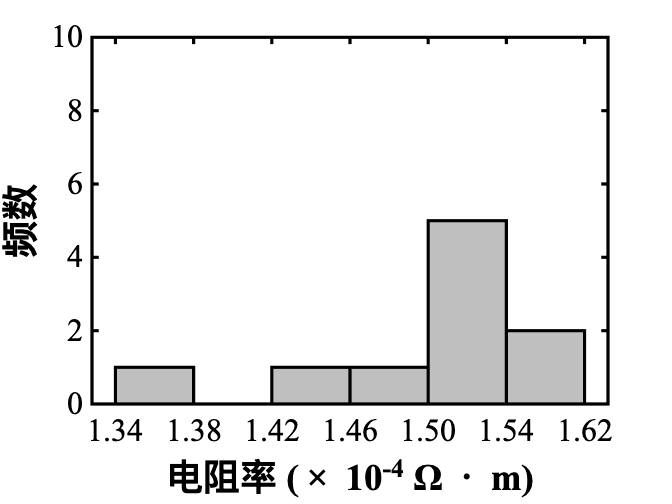

% =========================================================================
% 学术期刊发表级：薄片电阻率直方图 (单位换算为 Ohm*m)
% =========================================================================

% 1. 定义真实数据
counts = [1, 0, 1, 1, 5, 2]; 

% 2. 单位换算后的横坐标标签
% 原数据 (mOhm*cm): 13.4, 13.8, 14.2, 14.6, 15.0, 15.4, 16.2
% 换算为 (*10^-4 Ohm*m): 1.34, 1.38, 1.42, 1.46, 1.50, 1.54, 1.62
x_labels = {'1.34', '1.38', '1.42', '1.46', '1.50', '1.54', '1.62'};

% 3. 创建纯白背景画布 (符合出版标准)
figure('Color', 'w', 'Position', [200, 200, 600, 450]);
hold on;

% 4. 设置学术配色 (黑白灰，确保黑白打印绝对清晰)
barColor = [0.75, 0.75, 0.75]; % 标准学术灰
edgeColor = 'k';               % 纯黑边框

% 5. 绘制柱状图 
for i = 1:length(counts)
    if counts(i) > 0
        x_left = i - 0.5;
        x_right = i + 0.5;
        fill([x_left, x_right, x_right, x_left], [0, 0, counts(i), counts(i)], ...
             barColor, 'EdgeColor', edgeColor, 'LineWidth', 1.2);
    end
end

% 6. 坐标轴核心设置
ylim([0, 10]);
yticks(0:2:10);
xlim([0.2, 6.8]);
xticks(0.5:1:6.5);
xticklabels(x_labels);

% 开启全包围边框 (Box on)，刻度朝内 (in)，加粗坐标轴 (1.2pt)
set(gca, 'Box', 'on', 'TickDir', 'in', 'LineWidth', 1.2, ...
         'XColor', 'k', 'YColor', 'k', 'XMinorTick', 'off', 'YMinorTick', 'off');

% 设置全局坐标轴字体为 Times New Roman
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);

% 7. 添加轴标签 (包含换算后的量级和新单位)
xlabel('电阻率 (\times 10^{-4} \Omega \cdot m)', 'Interpreter', 'tex', ...
       'FontSize', 14, 'FontWeight', 'bold', 'Color', 'k');

ylabel('频数', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'k');

hold off;

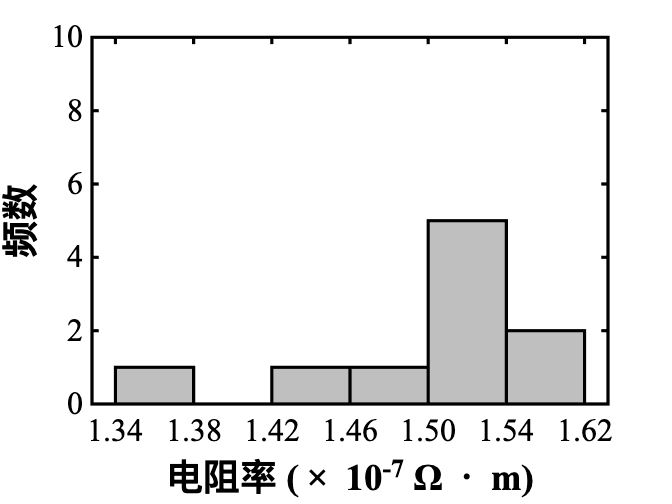

% =========================================================================
% 学术期刊发表级：薄片电阻率直方图 (修正厚度误差后，单位为 Ohm*m)
% =========================================================================

% 1. 定义真实频数数据
counts = [1, 0, 1, 1, 5, 2]; 

% 2. 修正后的横坐标标签
% 原错误数据 (mOhm*cm): 13.4, 13.8, 14.2, 14.6, 15.0, 15.4, 16.2
% 真实数据 (缩小1000倍，换算为 *10^-7 Ohm*m): 1.34, 1.38, 1.42, 1.46, 1.50, 1.54, 1.62
x_labels = {'1.34', '1.38', '1.42', '1.46', '1.50', '1.54', '1.62'};

% 3. 创建纯白背景画布 (符合出版标准)
figure('Color', 'w', 'Position', [200, 200, 600, 450]);
hold on;

% 4. 设置学术配色 (黑白灰，确保黑白打印绝对清晰)
barColor = [0.75, 0.75, 0.75]; % 标准学术灰
edgeColor = 'k';               % 纯黑边框

% 5. 绘制柱状图 
for i = 1:length(counts)
    if counts(i) > 0
        x_left = i - 0.5;
        x_right = i + 0.5;
        fill([x_left, x_right, x_right, x_left], [0, 0, counts(i), counts(i)], ...
             barColor, 'EdgeColor', edgeColor, 'LineWidth', 1.2);
    end
end

% 6. 坐标轴核心设置
ylim([0, 10]);
yticks(0:2:10);
xlim([0.2, 6.8]);
xticks(0.5:1:6.5);
xticklabels(x_labels);

% 开启全包围边框 (Box on)，刻度朝内 (in)，加粗坐标轴 (1.2pt)
set(gca, 'Box', 'on', 'TickDir', 'in', 'LineWidth', 1.2, ...
         'XColor', 'k', 'YColor', 'k', 'XMinorTick', 'off', 'YMinorTick', 'off');

% 设置全局坐标轴字体为 Times New Roman
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);

% 7. 添加轴标签 (包含新的真实量级 10^-7)
xlabel('电阻率 (\times 10^{-7} \Omega \cdot m)', 'Interpreter', 'tex', ...
       'FontSize', 14, 'FontWeight', 'bold', 'Color', 'k');

ylabel('频数', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'k');

hold off;